# **Cálculo de la ganancia del observador**

El siguiente sistema mecánico está descripto por el sistema de ecuaciones. 

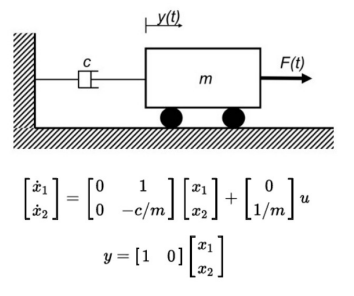

Donde m=1 , c=1 , x1 es la posición de la masa, x2 es la velocidad de la masa, u es la fuerza e y es la posición.

**1)** Determine si el sistema es observable.

close all; clear all; clc;
% Definimos las matrices del sistema.
m = 1;
c = 1;
A = [0    1;
     0 -c/m];
B = [0;
     1/m];
C = [1 0];
observabilidad = obsv(A,C); % Matriz de observabilidad.
if rank(observabilidad) == 2
    fprintf('Rango de la matriz de observabilidad: ')
    disp(rank(observabilidad))
    fprintf('Sistema observable.\n')
end

Rango de la matriz de observabilidad: 

     2



Sistema observable.


**2)** Verifique si el sistema es observable para C=[0 1] . ¿Qué conclusión puede sacar?.

Cprima = [0 1];
observabilidad = obsv(A,Cprima); % Matriz de observabilidad.
if rank(observabilidad) == 2
    fprintf('Rango de la matriz de observabilidad: ')
    disp(rank(observabilidad))
    fprintf('Sistema observable.\n')
else
    fprintf('El sistema no es observable para C = [0 1],\nesto implica que no podremos estimar los estados\ninternos del sistema a partir de sensar la velocidad\ndel vehículo.\n')
end

El sistema no es observable para C = [0 1],
esto implica que no podremos estimar los estados
internos del sistema a partir de sensar la velocidad
del vehículo.


**3)** Si es sistema es observable con alguno de los sensores analizados, determine la ganancia del observador L=[l1 l2]^T para el polinomio característico deseado,

*pdes(s)=(s + p)^2*

El principio de diseño (rule of thumb) indica que los polos del observador a lazo cerrado deben ser entre 4 y 5 veces más rápidos que los polos del sistema a observar. ¿Dónde ubicaría los polos del observador según esta regla?

Siendo el sistema observable a partir de sensar la posición del vehículo, procedemos a obtener la ganacia del observador.

Comenzamos buscando los polos del sistema.

syms s % Variable compleja.
I = eye(2);
disp('Polinomio característico del sistema:')

Polinomio característico del sistema:


p_caracteristico = expand(det(s*I-A))

$$p\_caracteristico = s^{2}+s$$

C1_syms = coeffs(p_caracteristico,s); % Obtenemos los coeficientes simbólicos del polinomio característico.
C1_double = double(C1_syms); % Coeficientes formato double.
a2 = 0;
a1 = C1_double(1,2);
disp('Polos del polinomio del sistema:')

Polos del polinomio del sistema:


polos = roots([1 a1 a2]) % Polos del sistema.

polos =      0
    -1


Dado que los polos del observador  lazo cerrado deben ser entre 1 y 5 veces más rápidos que los polos del sistema, colocamos sus dos polos en $p=-5\;\textrm{rad}/s$.

p = -5; % Polos del polinomio deseado.
disp('Situamos los polos del observador en lazo cerrado en:')

Situamos los polos del observador en lazo cerrado en:


p

p = -5

disp('Polinomio deseado del observador a lazo cerrado:')

Polinomio deseado del observador a lazo cerrado:


p_deseado = expand((s + -1*p)^2) % Polinomio deseado.

$$p\_deseado = s^{2}+10\,s+25$$

C2_syms = coeffs(p_deseado, s); % Coeficientes del polinomio deseado.
C2_double = double(C2_syms); % Coeficientes en formato double.

syms l1 l2
L = [l1 l2]'; % Matriz de ganancia del obsv. a lazo cerrado.
p_observador = det(s*I - A + L*C)

$$p\_observador = s+\bar{l_{1}}+\bar{l_{2}}+s\,\bar{l_{1}}+s^{2}$$

C3_syms = coeffs(p_observador, s); % Coeficientes del polinomio del observador.

% Igualamos los coeficientes.
eqns = [C3_syms == C2_double];

% Resolvemos las ecuaciones.
sol = solve(eqns, [l1, l2]);

% Mostramos los coeficientes resultantes.
disp("Los coeficientes del polinomio simbólico son:");

Los coeficientes del polinomio simbólico son:


l1_double = double(sol.l1);
l2_double = double(sol.l2);
disp('l1:')

l1:


disp(l1_double);

     9



disp('l2:')

l2:


disp(l2_double);

    16




% Corroboramos:
polos_deseados = eig(A - [l1_double l2_double]'*C)

polos_deseados =     -5
    -5


% Corroboración.
L = acker(A',C',[p p])'

L =      9
    16
